**CODIGO MONTADO EM AULA**

Controller Auto-Regressive Integrated Moving-Average (CARIMA):

$A(q^{-1})y(k) = z^{-d}B(q^{-1})u(k-d)+\frac{1}{\Delta}\epsilon(k)$, onde: $\Delta = 1-q^{-1}$

clear, clc
z = tf('z');
s = tf('s');
delta = [1 -1];
H_siso = [1 0];

% DEFINIÇÃO DAS MATRIZES DE CONTROLE
% CAMACHO 4.4 (PDF 73)
A_1 = [1 -0.8];                               % MATRIZ DO SISTEMA
B_1 = [0.4 0.6];                              % MATRIZ DE ENTRADA
C_1 = [1 0];                                  % MODELO DE DISTURBIO

% JULIO 4.11 (P. 203)
A_2 = [1 -0.9];                               % MATRIZ DO SISTEMA
B_2 = [0.3 0];                                % MATRIZ DE ENTRADA
C_2 = [1 -0.4];                               % MODELO DE DISTURBIO
DT_2 = 1;

% CAMACHO 5.2.6 (PDF 109)
A_3 = [1 -0.8351];                            % MATRIZ DO SISTEMA
B_3 = [0.2713 0];                             % MATRIZ DE ENTRADA
C_3 = [1 0];                                  % MODELO DE DISTURBIO
DT_3 = 4;

% CAMACHO P139
Ts_4 = 0.03;
Y11 = 1/(1 + 0.7*s);
Y12 = 5/(1 + 0.3*s);
Y21 = 1/(1 + 0.5*s);
Y22 = 2/(1 + 0.4*s);

Y_mimo = [Y11 Y12; Y21 Y22];

% DISCRETIZA OS SISTEMAS
Y_d = c2d(Y_mimo, Ts_4)

Y_d =
 
  From input 1 to output...
        0.04195
   1:  ---------
       z - 0.958
 
        0.05824
   2:  ----------
       z - 0.9418
 
  From input 2 to output...
         0.4758
   1:  ----------
       z - 0.9048
 
         0.1445
   2:  ----------
       z - 0.9277
 
Sample time: 0.03 seconds
Discrete-time transfer function.



**ATIVIDADE 1:** CALCULAR A PREDIÇÃO USANDO A EQUAÇÃO


$$G(k) = \frac{b}{z-a}$$


com $a = 0.9$, $b = 0.2$ e horizonte de predição $N = 5$. F? G?

N = 5;
an = 2;                         % Tamanho denominador
At = conv(delta, [1 -0.9]);     % Calcula Ã

p1 = [1 zeros(1, an)];          % Primeiro polinimio
[q, ~] = deconv ([1 zeros(1, an)],At);

E = q;                          % Inicializa E
F = [];

for n = 1:N
    [q,r] = deconv(p1, At);     % DIVIDE OS POLINOMIOS
    E(n) = q;                   
    F = [F;r(2:end)];
    p1=[r(2:end), 0];
end

Ga = conv(E,[0.2 0]);
G = zeros(N);
for n = 1:N
    G(n:N, n) = Ga(1:N-n+1);
end

fprintf('\nMatriz E:');


Matriz E:

disp(E')

    1.0000
    1.9000
    2.7100
    3.4390
    4.0951



fprintf('\nMatriz F:');


Matriz F:

disp(F)

    1.9000   -0.9000
    2.7100   -1.7100
    3.4390   -2.4390
    4.0951   -3.0951
    4.6856   -3.6856



fprintf('\nMatriz G:');


Matriz G:

disp(G)

    0.2000         0         0         0         0
    0.3800    0.2000         0         0         0
    0.5420    0.3800    0.2000         0         0
    0.6878    0.5420    0.3800    0.2000         0
    0.8190    0.6878    0.5420    0.3800    0.2000



**ABORDAGEM SISO**

**ATIVIDADE 2:** OBTER A SIMULAÇÃO NO SIMULINK DO SISTEMA SISO

EXEMPLO 4.11 CAMACHO

A = A_1;
B = B_1;
C = C_1;

% QUANDO O SISTEMA E SIMULADO É ADICIONADO O ATRASO DO RETENTOR DE ORDEM
% 'ZOH' NO SISTEMA, RESULTANDO EM UM DESLOCAMENTO PARA ESQUERDA DE A 
% (ADICIONANDO UM ZERO A DIREITA), O ZERO A DIREITA EM B NÃO TEM EFEITO
P_siso = tf([0 B],[A 0],1);
H = [1 0];

N = 3;                                       % HORIZONTE DE PREDIÇÃO
Nu = 3;                                      % HORIZONTE DE CONTROLE
R = 0.8*eye(Nu);                              % PESOS DO CONTROLE
%R(1,1) = 0;
% FILTRO INTEGRADOR
At = conv(delta,A);                          % CALCULA Ã
an = length(A);                              % COLETA TAMANHO DO VETOR A

% ============================================================
% CALCULA Ã E Q
%[q, ~] = deconv ([1 zeros(1, an)],At);      % 1/At
[q, ~] = deconv ([C 0],At);

% ==================| INICIALIZA OS POLINOMIOS |==============
%p1 = [1 zeros(1, an)];
p1 = [C 0];

% =============| INICIALIZA AS MATRIZES DE ITERAÇÃO |=========
E = q;
F = [];

% ========================| ITERAÇÃO |========================
for n = 1:N
    [q,r] = deconv(p1, At);                 % DIVIDE OS POLINOMIOS
    E(n) = q;                   
    F = [F;r(2:end)];                       % 
    p1=[r(2:end), 0];
end

Ga = conv(deconv(E,C),B);                             % MATRIZ DINAMICA

% =====================| MATRIZ DINAMICA |====================
G = zeros(N);
for n = 1:N
    G(n:N, n) = Ga(1:N-n+1);
end
P_siso

P_siso =
 
  0.4 z + 0.6
  -----------
  z^2 - 0.8 z
 
Sample time: 1 seconds
Discrete-time transfer function.




fprintf('\nMatriz E:');


Matriz E:

disp(E')

    1.0000
    1.8000
    2.4400



fprintf('\nMatriz F:');


Matriz F:

disp(F)

    1.8000   -0.8000
    2.4400   -1.4400
    2.9520   -1.9520



fprintf('\nMatriz G:');


Matriz G:

disp(G)

    0.4000         0         0
    1.3200    0.4000         0
    1.0800    1.3200    0.4000




% ======================| OTIMIZAÇÃO |========================
%K = (G'*G + R)\G';                          % INCREMENTO OTIMO FUTURO

G_trunc = G(:, 1:Nu);           
K = (G_trunc' * G_trunc + R) \ G_trunc';

fprintf('\nMatriz K:');


Matriz K:

disp(K)

    0.1630    0.4220    0.0479
   -0.1160   -0.1344    0.4220
   -0.0096   -0.1160    0.1630




% =================| PARA USO NO SIMULINK |===================
Kr_siso = sum(K(1,:))

Kr_siso = 0.6329

KE_siso = K(1,:)*E'

KE_siso = 1.0394

KF_siso = K(1,:)*F

KF_siso =     1.4644   -0.8315



C_siso = C_1;

EXEMPLO 4.11 JULIO

A = A_2;
B = B_2;
C = C_2;

% QUANDO O SISTEMA E SIMULADO É ADICIONADO O ATRASO DO RETENTOR DE ORDEM
% 'ZOH' NO SISTEMA, RESULTANDO EM UM DESLOCAMENTO PARA ESQUERDA DE A 
% (ADICIONANDO UM ZERO A DIREITA), O ZERO A DIREITA EM B NÃO TEM EFEITO
P_siso_2 = tf([0 B],[A 0],1);
H = [1 0];

N = 3;                                       % HORIZONTE DE PREDIÇÃO
Nu = 3;                                      % HORIZONTE DE CONTROLE
R = 0.8*eye(Nu);                              % PESOS DO CONTROLE
%R(1,1) = 0;
% FILTRO INTEGRADOR
At = conv(delta,A);                          % CALCULA Ã
an = length(A);                              % COLETA TAMANHO DO VETOR A

% ============================================================
% CALCULA Ã E Q
%[q, ~] = deconv ([1 zeros(1, an)],At);      % 1/At
[q, ~] = deconv ([C 0],At);

% ==================| INICIALIZA OS POLINOMIOS |==============
%p1 = [1 zeros(1, an)];
p1 = [C 0];

% =============| INICIALIZA AS MATRIZES DE ITERAÇÃO |=========
E = q;
F = [];

% ========================| ITERAÇÃO |========================
for n = 1:N
    [q,r] = deconv(p1, At);                 % DIVIDE OS POLINOMIOS
    E(n) = q;                   
    F = [F;r(2:end)];                       % 
    p1=[r(2:end), 0];
end

Ga = conv(deconv(E,C),B);                             % MATRIZ DINAMICA

% =====================| MATRIZ DINAMICA |====================
G = zeros(N);
for n = 1:N
    G(n:N, n) = Ga(1:N-n+1);
end

P_siso_2

P_siso_2 =
 
     0.3 z
  -----------
  z^2 - 0.9 z
 
Sample time: 1 seconds
Discrete-time transfer function.




fprintf('\nMatriz E:');


Matriz E:

disp(E')

    1.0000
    1.5000
    1.9500



fprintf('\nMatriz F:');


Matriz F:

disp(F)

    1.5000   -0.9000
    1.9500   -1.3500
    2.3550   -1.7550



fprintf('\nMatriz G:');


Matriz G:

disp(G)

    0.3000         0         0
    0.5700    0.3000         0
         0    0.5700    0.3000




% ======================| OTIMIZAÇÃO |========================
%K = (G'*G + R)\G';                          % INCREMENTO OTIMO FUTURO

G_trunc = G(:, 1:Nu);           
K = (G_trunc' * G_trunc + R) \ G_trunc';

fprintf('\nMatriz K:');


Matriz K:

disp(K)

    0.2521    0.4425   -0.0623
   -0.0365    0.1898    0.4425
    0.0070   -0.0365    0.2521




% =================| PARA USO NO SIMULINK |===================
Kr_siso_2 = sum(K(1,:))

Kr_siso_2 = 0.6323

KE_siso_2 = K(1,:)*E'

KE_siso_2 = 0.7943

KF_siso_2 = K(1,:)*F

KF_siso_2 =     1.0942   -0.7149



C_siso_2 = C;

## **ABORDAGEM EM ESPAÇOS DE ESTADOS**

**ATIVIDADE 3: **TESTAR DIFERENTES VALORES DE C1 E C2 E OBSERVAR OS RESULTADOS

**RESULTADOS:** *OS VALORES DE C1 E C2 ATUAM NA VELOCIDADE DO CONTROLADOR NA REJEIÇÃO DE RUIDOS SEM AFETAR O SEGUIMENTO DE REFERÊNCIA.*

A = A_1;
B = B_1;

N = 100;                                       % HORIZONTE DE PREDIÇÃO
Nu = 50;                                      % HORIZONTE DE CONTROLE
R = 0.8*eye(Nu);                              % PESOS DO CONTROLE

P_ss = tf([0 B],[A 0],1);

% FILTRO INTEGRADOR
At = conv(delta,A);                          % CALCULA Ã
an = length(A);                              % COLETA TAMANHO DO VETOR A

% DEFINIÇÃO DO MODELO DE PERTURBAÇÃO
polC = conv([1 -0.2],[1 -0.6]);              % POSICIONA DOIS POLOS
c1 = polC(2);                                % PARAMETROS DE AJUSTE 
c2 = polC(3);                                % DO OBSERVADOR
%c1 = 0; 
%c2 = 0;

CP = [c1 c2];

A_ss = [-At(1,2:end)' eye(an, an - 1)];      % MATRIZ DO SISTEMA
D = (CP - At(1,2:end))';

% =============| INICIALIZA AS MATRIZES DE ITERAÇÃO |=========
Ga = [];
F =  [];
E =  [];

%============| ITERAÇÃO PRA OBTER O ESTADO FUTURO |===========
for i = 0:N-1
    Ga = [Ga H*A_ss^i*B'];
    F = [F; H*A_ss^(i+1)];
    E = [E; H*A_ss^i*D];
end

% =====================| MATRIZ DINAMICA |====================
G = zeros(N);
for n = 1:N
    G(n:N, n) = Ga(1:N-n+1);
end

fprintf('\nMatriz G:');


Matriz G:

disp(G)

  Columns 1 through 13

    0.4000         0         0         0         0         0         0         0         0         0         0         0         0
    1.3200    0.4000         0         0         0         0         0         0         0         0         0         0         0
    2.0560    1.3200    0.4000         0         0         0         0         0         0         0         0         0         0
    2.6448    2.0560    1.3200    0.4000         0         0         0         0         0         0         0         0         0
    3.1158    2.6448    2.0560    1.3200    0.4000         0         0         0         0         0         0         0         0
    3.4927    3.1158    2.6448    2.0560    1.3200    0.4000         0         0         0         0         0         0         0
    3.7941    3.4927    3.1158    2.6448    2.0560    1.3200    0.4000         0         0         0         0         0         0
    4.0353    3.7941    3.4927    3.1158    2.6448    2.056

fprintf('\nMatriz E:');


Matriz E:

disp(E)

    1.0000
    1.1200
    1.2160
    1.2928
    1.3542
    1.4034
    1.4427
    1.4742
    1.4993
    1.5195
    1.5356
    1.5485
    1.5588
    1.5670
    1.5736
    1.5789
    1.5831
    1.5865
    1.5892
    1.5914
    1.5931
    1.5945
    1.5956
    1.5965
    1.5972
    1.5977
    1.5982
    1.5985
    1.5988
    1.5991
    1.5993
    1.5994
    1.5995
    1.5996
    1.5997
    1.5998
    1.5998
    1.5998
    1.5999
    1.5999
    1.5999
    1.5999
    1.5999
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000
    1.6000

fprintf('\nMatriz F:');


Matriz F:

disp(F)

    1.8000    1.0000
    2.4400    1.8000
    2.9520    2.4400
    3.3616    2.9520
    3.6893    3.3616
    3.9514    3.6893
    4.1611    3.9514
    4.3289    4.1611
    4.4631    4.3289
    4.5705    4.4631
    4.6564    4.5705
    4.7251    4.6564
    4.7801    4.7251
    4.8241    4.7801
    4.8593    4.8241
    4.8874    4.8593
    4.9099    4.8874
    4.9279    4.9099
    4.9424    4.9279
    4.9539    4.9424
    4.9631    4.9539
    4.9705    4.9631
    4.9764    4.9705
    4.9811    4.9764
    4.9849    4.9811
    4.9879    4.9849
    4.9903    4.9879
    4.9923    4.9903
    4.9938    4.9923
    4.9950    4.9938
    4.9960    4.9950
    4.9968    4.9960
    4.9975    4.9968
    4.9980    4.9975
    4.9984    4.9980
    4.9987    4.9984
    4.9990    4.9987
    4.9992    4.9990
    4.9993    4.9992
    4.9995    4.9993
    4.9996    4.9995
    4.9997    4.9996
    4.9997    4.9997
    4.9998    4.9997
    4.9998    4.9998
    4.9999    4.9998
    4.9999    4.9999
    4.9999   


% ======================| OTIMIZAÇÃO |========================
%K = (G'*G + R)\G';

G_trunc = G(:, 1:Nu);           
K = (G_trunc' * G_trunc + R) \ G_trunc';

fprintf('\nMatriz K:');


Matriz K:

disp(K)

  Columns 1 through 13

    0.1311    0.2802    0.1511    0.0375   -0.0078   -0.0128   -0.0065   -0.0015    0.0004    0.0006    0.0003    0.0001   -0.0000
   -0.1525   -0.1947    0.1046    0.1075    0.0466    0.0071   -0.0052   -0.0048   -0.0020   -0.0002    0.0003    0.0002    0.0001
   -0.0198   -0.1947   -0.2175    0.0989    0.1087    0.0485    0.0081   -0.0050   -0.0049   -0.0021   -0.0003    0.0002    0.0002
    0.0194    0.0217   -0.1724   -0.2119    0.0978    0.1068    0.0475    0.0079   -0.0049   -0.0048   -0.0020   -0.0003    0.0002
    0.0165    0.0547    0.0407   -0.1676   -0.2129    0.0961    0.1059    0.0473    0.0079   -0.0049   -0.0048   -0.0020   -0.0003
    0.0064    0.0303    0.0621    0.0425   -0.1680   -0.2136    0.0958    0.1059    0.0474    0.0080   -0.0049   -0.0048   -0.0020
    0.0006    0.0078    0.0310    0.0623    0.0425   -0.1681   -0.2136    0.0958    0.1059    0.0474    0.0080   -0.0049   -0.0048
   -0.0009   -0.0014    0.0067    0.0308    0.0623    0.042


% =================| PARA USO NO SIMULINK |===================
A_ss = A;
B_ss = B;
D_ss = D;
H_ss = [1 0]

H_ss =      1     0



Kr_ss = sum(K(1,:))

Kr_ss = 0.5725

KE_ss = K(1,:)*E

KE_ss = 0.6389

KF_ss = K(1,:)*F

KF_ss =     1.3845    1.0149



eig(A_ss-B'*KF_ss)

ans =     0.3287
   -1.2914


eig(A_ss-D*H)

ans =   -0.4000 + 1.0881i
  -0.4000 - 1.0881i


## **DISTURBIO**

**ATIVIDADE 4: **INVESTIGAR O DISTURBIO NO SISTEMA

A = A_3;                    % Polinômio A(q^-1)
B = B_3;                    % Polinômio B(q^-1) sem atraso embutido
Ts = 1;
DT_incerteza = 1;

%% MODELO CARIMA EM ESPAÇO DE ESTADOS
At = conv(delta, A);            % Ã(q^-1) = A(q^-1) * Delta

%% DEFINIÇÃO DO MODELO DE PERTURBAÇÃO
polC = conv([1 -0.9], [1 -0.9]);    % Cria C(q^-1) = (1 - q^-1)^2
c1 = polC(2);
c2 = polC(3);

%% ========================================================================
% BLOCO DE ANÁLISE DE ROBUSTEZ DINÂMICO (VERSÃO DEFINITIVA E CORRETA)
% =========================================================================
fprintf('\nAnalisando robustez para C(z) = 1 + (%.2f)z^{-1} + (%.2f)z^{-2}\n', c1, c2);


Analisando robustez para C(z) = 1 + (-1.80)z^{-1} + (0.81)z^{-2}


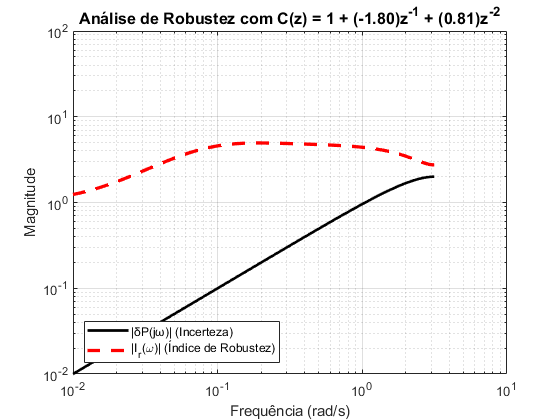


% 1. Definição da faixa de frequência para análise
w = logspace(-2, log10(pi/Ts), 500);

% 2. Modelo da Incerteza Multiplicativa
% Usa a variável de incerteza para o teste
delta_P_num = [1 zeros(1, DT_incerteza-1) -1];
delta_P_den = [1 zeros(1, DT_incerteza)];
delta_P = tf(delta_P_num, delta_P_den, Ts);
mag_delta_P = squeeze(abs(freqresp(delta_P, w)));

% 3. Cálculo do Índice de Robustez usando o MODELO CORRETO
% Cria a FT do filtro C(z) dinamicamente
C_tf = tf([1 c1 c2], 1, Ts);

% ** CORREÇÃO FUNDAMENTAL: Cria a FT da planta GPC (b/At) para a análise **
P_gpc = tf([0 B], At, Ts); % Note o uso de 'At' no denominador

% Calcula a função de transferência de malha L(z) = C(z)*P_GPC(z)
L = C_tf * P_gpc; 

% Calcula a magnitude do índice de robustez
Ir_freqresp = (1 + freqresp(L, w)) ./ freqresp(L, w);
mag_Ir = squeeze(abs(Ir_freqresp));

% 4. Plot dos resultados
figure;
loglog(w, mag_delta_P, 'k-', 'LineWidth', 2);
hold on;
loglog(w, mag_Ir, 'r--', 'LineWidth', 2.5);
hold off;

title_str = sprintf('Análise de Robustez com C(z) = 1 + (%.2f)z^{-1} + (%.2f)z^{-2}', c1, c2);
title(title_str, 'FontSize', 12);
xlabel('Frequência (rad/s)', 'FontSize', 11);
ylabel('Magnitude', 'FontSize', 11);
legend('|δP(jω)| (Incerteza)', '|I_r(\omega)| (Índice de Robustez)', 'Location', 'southwest');
grid on;
ylim([1e-2 1e2]);

## **ABORDAGEM EM ESPAÇOS DE ESTADOS COM PRESENÇA DE ATRASO**

**ATIVIDADE 5: **TESTAR A PRESENÇA DE ATRASO NO SISTEMA

A = A_3;
B = B_3;
C = C_3;

P_ss_DT = tf([0 B],[A 0],1);

N = 100;                                     % HORIZONTE DE PREDIÇÃO
Nu = 100;                                    % HORIZONTE DE CONTROLE
R = 0.8*eye(Nu);                             % PESOS DO CONTROLE

% FILTRO INTEGRADOR
At = conv(delta,A);                          % CALCULA Ã
an = length(A);                              % COLETA TAMANHO DO VETOR A

% DEFINIÇÃO DO MODELO DE PERTURBAÇÃO
polC = conv([1 -0.5],[1 -0.5]);                % POSICIONA DOIS POLOS
c1 = polC(2);                                % PARAMETROS DE AJUSTE 
c2 = polC(3);                                % DO OBSERVADOR
CP = [c1 c2];

A_ss = [-At(1,2:end)' eye(an, an - 1)];      % MATRIZ DO SISTEMA
D = (CP - At(1,2:end))';


% =============| INICIALIZA AS MATRIZES DE ITERAÇÃO |=========
Ga = [];
F =  [];
E =  [];

%============| ITERAÇÃO PRA OBTER O ESTADO FUTURO |===========
for i = 0:N-1
    Ga = [Ga H*A_ss^i*B'];
    F = [F; H*A_ss^(i+1)];
    E = [E; H*A_ss^i*D];
end

% =====================| MATRIZ DINAMICA |====================
G = zeros(N);
for n = 1:N
    G(n:N, n) = Ga(1:N-n+1);
end

FIR = [];

for i = 0:DT_3
    FIR = [FIR A_ss^i*B'];
end

% ======================| OTIMIZAÇÃO |========================
%K = (G'*G + R)\G';

G_trunc = G(:, 1:Nu);           
K = (G_trunc' * G_trunc + R) \ G_trunc';

Kr_ss_DT = sum(K(1,:))

Kr_ss_DT = 0.8021

KE_ss_DT = K(1,:)*E

KE_ss_DT = 0.8025

KF_ss_DT = K(1,:)*F

KF_ss_DT =     2.2960    1.7889



A_ss_DT = A_ss

A_ss_DT =     1.8351    1.0000
   -0.8351         0


B_ss_DT = B

B_ss_DT =     0.2713         0


D_ss_DT = D

D_ss_DT =     0.8351
   -0.5851


H_ss_DT = [1 0]

H_ss_DT =      1     0



fprintf('\nMatriz E:');


Matriz E:

disp(E)

    0.8351
    0.9474
    1.0412
    1.1195
    1.1849
    1.2395
    1.2851
    1.3232
    1.3550
    1.3816
    1.4037
    1.4223
    1.4377
    1.4506
    1.4614
    1.4704
    1.4780
    1.4843
    1.4895
    1.4939
    1.4975
    1.5006
    1.5031
    1.5053
    1.5071
    1.5085
    1.5098
    1.5108
    1.5117
    1.5124
    1.5130
    1.5135
    1.5139
    1.5143
    1.5146
    1.5148
    1.5150
    1.5152
    1.5153
    1.5155
    1.5156
    1.5156
    1.5157
    1.5158
    1.5158
    1.5159
    1.5159
    1.5159
    1.5160
    1.5160
    1.5160
    1.5160
    1.5160
    1.5160
    1.5160
    1.5160
    1.5160
    1.5160
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161
    1.5161

fprintf('\nMatriz F:');


Matriz F:

disp(F)

    1.8351    1.0000
    2.5325    1.8351
    3.1149    2.5325
    3.6012    3.1149
    4.0074    3.6012
    4.3466    4.0074
    4.6298    4.3466
    4.8664    4.6298
    5.0639    4.8664
    5.2289    5.0639
    5.3666    5.2289
    5.4817    5.3666
    5.5777    5.4817
    5.6580    5.5777
    5.7250    5.6580
    5.7809    5.7250
    5.8277    5.7809
    5.8667    5.8277
    5.8993    5.8667
    5.9265    5.8993
    5.9492    5.9265
    5.9682    5.9492
    5.9840    5.9682
    5.9973    5.9840
    6.0083    5.9973
    6.0175    6.0083
    6.0252    6.0175
    6.0317    6.0252
    6.0371    6.0317
    6.0415    6.0371
    6.0453    6.0415
    6.0484    6.0453
    6.0510    6.0484
    6.0532    6.0510
    6.0550    6.0532
    6.0566    6.0550
    6.0578    6.0566
    6.0589    6.0578
    6.0598    6.0589
    6.0605    6.0598
    6.0611    6.0605
    6.0617    6.0611
    6.0621    6.0617
    6.0625    6.0621
    6.0628    6.0625
    6.0630    6.0628
    6.0632    6.0630
    6.0634   

fprintf('\nMatriz G:');


Matriz G:

disp(G)

  Columns 1 through 13

    0.2713         0         0         0         0         0         0         0         0         0         0         0         0
    0.4979    0.2713         0         0         0         0         0         0         0         0         0         0         0
    0.6871    0.4979    0.2713         0         0         0         0         0         0         0         0         0         0
    0.8451    0.6871    0.4979    0.2713         0         0         0         0         0         0         0         0         0
    0.9770    0.8451    0.6871    0.4979    0.2713         0         0         0         0         0         0         0         0
    1.0872    0.9770    0.8451    0.6871    0.4979    0.2713         0         0         0         0         0         0         0
    1.1792    1.0872    0.9770    0.8451    0.6871    0.4979    0.2713         0         0         0         0         0         0
    1.2561    1.1792    1.0872    0.9770    0.8451    0.687


eig(A_ss-B'*KF_ss)

ans =    0.7297 + 0.2695i
   0.7297 - 0.2695i


eig(A_ss-D*H)

ans =     0.5000
    0.5000


## **SISTEMAS MIMO**

**ATIVIDADE 6: **TESTAR O SISTEMA MIMO

O modelo discretizado é dado por:


$$y_{1}(t) = \frac{b_{1}}{(1-a_{1}q^{-1})}u_{1}(t) + \frac{b_{2}}{(1-a_{2}q^{-1})}u_{2}(t)$$



$$y_{2}(t) = \frac{b_{3}}{(1-a_{3}q^{-1})}u_{1}(t) + \frac{b_{4}}{(1-a_{4}q^{-1})}u_{2}(t)$$


O objetivo e obter um modelo CARIMA


$$A(q^{-1})y(k) = z^{-d}B(q^{-1})u(k-d)+\frac{1}{\Delta}\epsilon(k)$$


O modelo discretizado e manipulado de seguinte forma:


$$(1-a_{1}q^{-1})(1-a_{2}q^{-1})y_{1}(t) = (1-a_{2}q^{-1})b_{1}u_{1}(t) + (1-a_{1}q^{-1})b_{2}u_{2}(t)$$


E em seguinda somando o modelo de disturbios:


$$(1-a_{1}q^{-1})(1-a_{2}q^{-1})y_{1}(t) = (1-a_{2}q^{-1})b_{1}u_{1}(t) + (1-a_{1}q^{-1})b_{2}u_{2}(t) + \frac{C_{1}(q^{-1})e(t)}{\Delta}$$


Onde delta: $\Delta = 1-q^{-1}$, multiplicando ambos os lados pelo $\Delta$


$$\Delta(1-a_{1}q^{-1})(1-a_{2}q^{-1})y_{1}(t) = (1-a_{2}q^{-1})b_{1}\Delta u_{1}(t) + (1-a_{1}q^{-1})b_{2}\Delta u_{2}(t) + D_{1}(q^{-1})e(t)$$



$$Ã_{1} y_{1}(t) = B_{11}\Delta u_{1}(t) + B_{12}\Delta u_{2}(t) + D(q^{-1})e(t)$$


A definição de $y_{2}$ segue esse mesmo procedimento. Para o modelo geral é definido as matrizes:

$A_{1}=\left[\matrix{ Ã_{1}^{T} & I_{N} \cr \vdots & 0_{1xN}}\right]_{NxN}$, $D_{1} = \left[\matrix{P - Ã_{1}} \right]$.

Onde $P = \left[\matrix{p_{1} \cr p_{2} \cr p_{3}} \right]$ e $p_{1-3}$ são os polos de um polinomio.


$$x_{1}(t+1) = A_{1}x(t)+B_{11}\Delta u_{1}(t)+B_{12}\Delta u_{2}(t)+D_{1}e(t)$$



$$y_{1}= \left[\matrix{1 & 0 & 0} \right]x_{1}(t)+e(t) \rightarrow y_{1}(t) = H_{1}x_{1}(t)+e(t)$$


Para $x_{2}(t+1)$a definição e semelhante. A matriz generalizada e construida apatir das matrizes obtidas:


$$x(t+1)=\left[\matrix{ A_{1} & 0 \cr 0 & A_{2}} \right]x(t)+\left[\matrix{B_{11} & B_{12} \cr B_{21}& B_{22}} \right]\Delta u(t) + \left[\matrix{ D_{1} & 0 \cr 0 & D_{2}} \right]e(t) \rightarrow x(t+1) = Ax(t) + B\Delta u(t) + D e(t)$$



$$y(t)=\left[\matrix{ H_{1} & 0 \cr 0 & H_{2}} \right]+e(t) \rightarrow y(t)=Hx(t)+e(t)$$


**ATIVIDADE 6:** IMPLEMENTAR SIMULAÇÃO DE SISTEMA MIMO

N = 3;           % horizonte de predição
Nu = 2;          % Horizonte de controle

Ts = Ts_4;

% MATRIZES DE AJUSTE
R = 1*zeros(2*Nu);
Q = 1*zeros(2*Nu);

for i = 1:2*Nu
    if(rem(i,2) == 0)
        R(i,i) = 0.05;
        Q(i,i) = 1;
    else
        R(i,i) = 0.05;
        Q(i,i) = 1;
    end
end

disp(R)

    0.0500         0         0         0
         0    0.0500         0         0
         0         0    0.0500         0
         0         0         0    0.0500



disp(Q)

     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1




const = 0.9;

% =============================================
polC = conv(conv([1 -const],[1 -const]),[1 -const]);
P = [polC(2) polC(3) polC(4)]';

% =============================================

%C = [c1 c2 c3]'
H1 = [1 0 0];
H2 = [1 0 0];

% MONTA MATRIZ H
H = [H1 zeros(1,3); zeros(1,3) H2];

%Integrador = [tf([1 0],Delta,Ts),0;0,tf([1 0],Delta,Ts)]

% CALCULA AS MATRIZES A E B
A = zeros(6);
D = zeros(6,2);
B = [];

for i = 1:2
    [num1, den1] = tfdata(Y_d(i,1), 'v');
    [num2, den2] = tfdata(Y_d(i,2), 'v');
    
    Aaux = conv(conv(den1, den2), delta);
    Baux1 = [conv(num1, den2) 0]';
    Baux2 = [conv(num2, den1) 0]';
    
    A(1+3*(i-1):3+3*(i-1), 1+3*(i-1):3+3*(i-1)) = [-Aaux(1, 2:4)' [eye(2); 0 0]];
    
    D(1+3*(i-1):3+3*(i-1),i) = (P - Aaux(1,2:4)');
    
    B = [B; Baux1(2:4,1) Baux2(2:4,1)];
    
end

clear num1 num2 den1 den2 Baux1 Baux2 Aaux

F =  [];
E =  [];

for i = 0:N-1
    F = [F; H*A^(i+1)];
    E = [E; H*A^i*D];
end


% ==========================================================
G = zeros(2*N,2*Nu);
for i = 1:N
    for j = 1:2
        if(i>=j)
            G(2*i-1:2*i,2*j-1:2*j) = H*A^(i-j)*B;
        end
    end
end

% ==========================================================
K = (G'*G+R)\G';
K = K(1:2,:);

% CALCULA Kr
Kr = zeros(2);

for i = 1:N
    Kr = Kr+[K(1,1+(2*(i-1))) K(1,2*i);
             K(2,1+(2*(i-1))) K(2,2*i)];
end

KE_mimo = K*E

KE_mimo =    -0.1324    0.5193
    0.2488    0.0179


KF_mimo = K*F

KF_mimo =    -5.4992   -3.2339   -1.5144   19.2357   10.9934    4.9226
    5.4411    2.2932    0.4021   -0.6385   -0.6248   -0.4774


Kr_mimo = Kr

Kr_mimo =    -0.7876    2.9845
    1.5178    0.1125



A_mimo = A;
B_mimo = B;
D_mimo = D;
H_mimo = H;

fprintf('\nMatriz G:');


Matriz G:

disp(G)

    0.0420    0.4758         0         0
    0.0582    0.1445         0         0
    0.0821    0.9063    0.0420    0.4758
    0.1131    0.2786    0.0582    0.1445
    0.1206    1.2959    0.0821    0.9063
    0.1647    0.4030    0.1131    0.2786



fprintf('\nMatriz E:');


Matriz E:

disp(E)

    0.1629         0
         0    0.1695
    0.1666         0
         0    0.1732
    0.1701         0
         0    0.1767



fprintf('\nMatriz F:');


Matriz F:

disp(F)

    2.8629    1.0000         0         0         0         0
         0         0         0    2.8695    1.0000         0
    5.4664    2.8629    1.0000         0         0         0
         0         0         0    5.4909    2.8695    1.0000
    8.7014    5.4664    2.8629         0         0         0
         0         0         0    8.7581    5.4909    2.8695

